clear all
addpath("./Sociodynamics/CollectiveRisk/")

tspan   = 1:1:250;
MCsteps = 1:1:40;

%%% Initial conditions
intlEndowment = 10; % "b" in paper; the initial endowment. If the agents are given small rewards for winning collective-risk games, does that constitute a slowly-driven system?
numAgents = 200;
randomNumbers = int32(randi([0, 1], [1, numAgents])); % randomly select whether an agent is a cooperator or defector
vecAgents = cell(numAgents,1);

kappa  = 0.5; 
alpha_ = 0.8;
c      = 1;
beta_  = 1;
Length = 50;
Width  = 50;

%%% Define initial positions of each agent.
idx_x0 = 10;
idx_y0 = 10;

tot_idx = 0; 
for idx_y = idx_y0:1:(idx_y0 + 9)
	for idx_x = idx_x0:1:(idx_x0 + 9)
		tot_idx = tot_idx + 1;		
		initial_positions(tot_idx, 1) = idx_x;
		initial_positions(tot_idx, 2) = idx_y;
	end
end
for idx_y = (idx_y0+15):1:(idx_y0 + 24)
	for idx_x = (idx_x0+15):1:(idx_x0 + 24)
		tot_idx = tot_idx + 1;		
		initial_positions(tot_idx, 1) = idx_x;
		initial_positions(tot_idx, 2) = idx_y;
	end
end
disp(tot_idx)

   200




matCoops = [];
cellResults = {};
idx_ = 1;
for alpha_ = [0.2, 0.4, 0.6, 0.8, 0.9]
    parameters = [kappa, alpha_, c, beta_, Length, Width];
    results_ = riskDrivenMigration(tspan, MCsteps, intlEndowment, randomNumbers, vecAgents, parameters, initial_positions);
    vecCoops = results_.('vecCoops');
    matCoops = [matCoops; vecCoops];
    cellResults{idx_} = results_;
    idx_ = idx_ + 1;
end

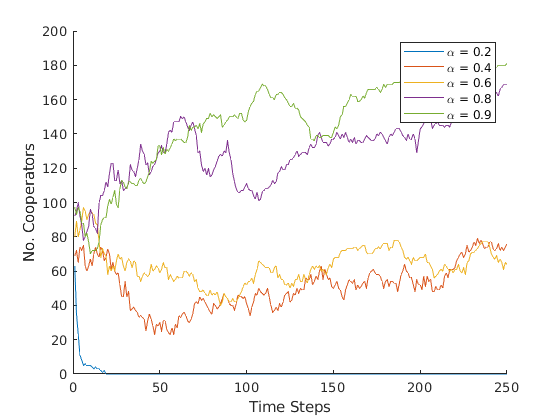

hold on
for i=1:5
    plot(matCoops(i,:))
end
legend('\alpha = 0.2','\alpha = 0.4', ...
        '\alpha = 0.6','\alpha = 0.8', ...
        '\alpha = 0.9')
ylabel('No. Cooperators')
xlabel('Time Steps')
hold off

cellResults{4}

ans = struct with fields:
       vecCoops: [1×250 int32]
    environment: [1×1 Environment]
         Agents: {200×1 cell}
     TimeSeries: [1×1 struct]


grid_arr = grid2arr(cellResults{3}.('environment'));
overlayD = grid_arr.Defectors;
overlayC = grid_arr.Cooperators;

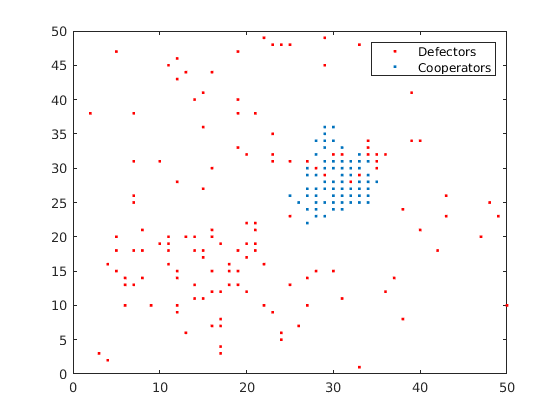

plot(overlayD(:,1), overlayD(:,2), '.r')
hold on
plot(overlayC(:,1), overlayC(:,2), '.')
legend('Defectors', 'Cooperators')
ylim([0,50])
xlim([0,50])
hold off

timeSeries = cellResults{3}.TimeSeries;
size(timeSeries.Defectors)

ans =      1    25


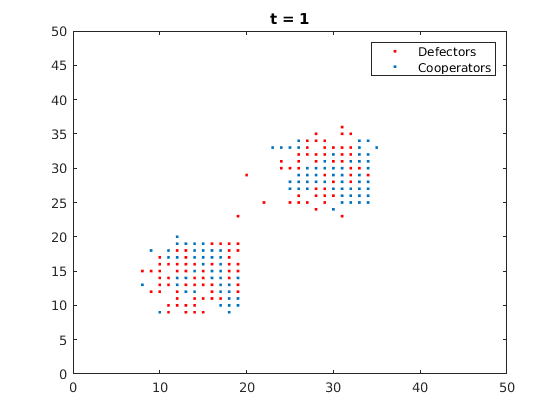

plot(timeSeries.Defectors{1}(:,1), timeSeries.Defectors{1}(:,2), '.r')
hold on
plot(timeSeries.Cooperators{1}(:,1), timeSeries.Cooperators{1}(:,2), '.')
title('t = 1');
legend('Defectors', 'Cooperators')
xlim([0,50])
ylim([0,50])
hold off

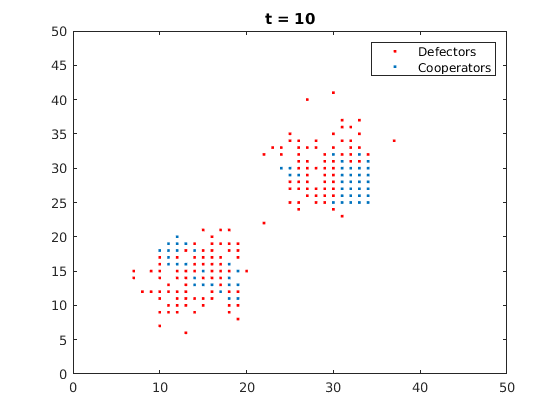

plot(timeSeries.Defectors{2}(:,1), timeSeries.Defectors{2}(:,2), '.r')
hold on
plot(timeSeries.Cooperators{2}(:,1), timeSeries.Cooperators{2}(:,2), '.')
title('t = 10');
legend('Defectors', 'Cooperators')
xlim([0,50])
ylim([0,50])
hold off

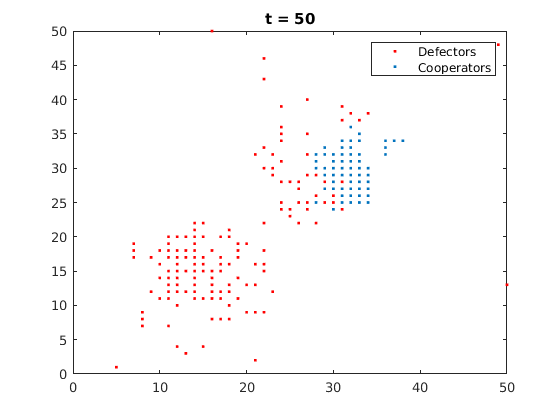

plot(timeSeries.Defectors{6}(:,1), timeSeries.Defectors{6}(:,2), '.r')
hold on
plot(timeSeries.Cooperators{6}(:,1), timeSeries.Cooperators{6}(:,2), '.')
legend('Defectors', 'Cooperators')
title('t = 50');
xlim([0,50])
ylim([0,50])
hold off

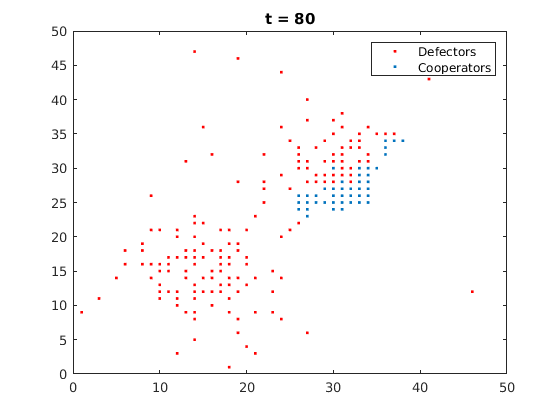

plot(timeSeries.Defectors{9}(:,1), timeSeries.Defectors{9}(:,2), '.r')
hold on
plot(timeSeries.Cooperators{9}(:,1), timeSeries.Cooperators{9}(:,2), '.')
legend('Defectors', 'Cooperators')
title('t = 80');
xlim([0,50])
ylim([0,50])
hold off

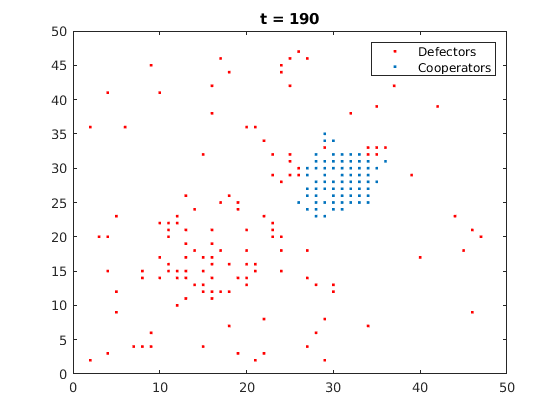

plot(timeSeries.Defectors{20}(:,1), timeSeries.Defectors{20}(:,2), '.r')
hold on
plot(timeSeries.Cooperators{20}(:,1), timeSeries.Cooperators{20}(:,2), '.')
title('t = 190');
legend('Defectors', 'Cooperators')
xlim([0,50])
ylim([0,50])
hold off

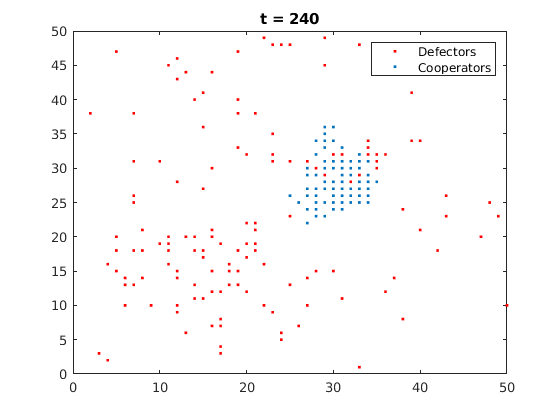

plot(timeSeries.Defectors{25}(:,1), timeSeries.Defectors{25}(:,2), '.r')
hold on
plot(timeSeries.Cooperators{25}(:,1), timeSeries.Cooperators{25}(:,2), '.')
legend('Defectors', 'Cooperators')
title('t = 240');
xlim([0,50])
ylim([0,50])
hold off